# Milestone 1

Bill and Declan

## Parameters

We settled on this set of parameters through a mix of looking up constants and conjecturing possible values. For example, the Inductance of the solenoid, pole strength, or resistance were all derived from reasonable guesses for possible components. The mass and dimensions of parts were estimated by looking at past recordings and common online parts.

struct_params = struct();
% Radius of the electromagnet coil
% - Units: m
struct_params.r = 0.018/2;

% Length of the electromagnet coil
% - Units: m
struct_params.l = 0.034; % Length of inductor (m)

% Lumped scaling constant: A m^3
% - winding_count*mu_core
% - Units: kg m^3 / s^2 A = N m^2 / A
struct_params.k = 1;

% Magnitude of the magnetic dipole moment of the permanent magnet
% - Units: amp-meters^2
struct_params.m = 1e-6;

% Resistance of the coil
% - Units: Ohms
struct_params.R = 2.41;
struct_params.m = 0.05; % Mass of permanent magnet

## V = 0

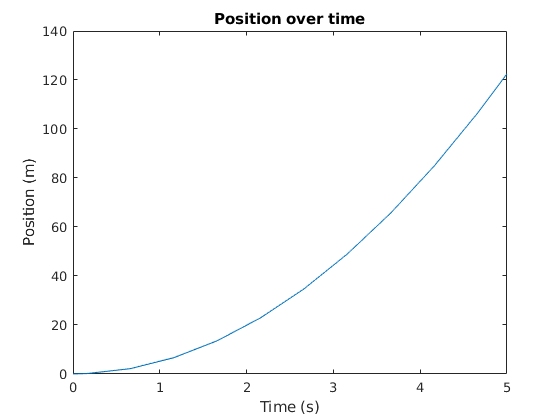

y0 = [0.05; 0];
tspan = [0 5];

v = 0;
[t, y] = sim_magnet(tspan, y0, v, struct_params);

figure();

plot(t, y(:, 1))
title("Position over time")
xlabel("Time (s)")
ylabel("Position (m)")

fprintf("Final Z: %.2f", y(end, 1))

Final Z: 122.55

The theoretical final Z can be obtained through the simple kinematic equation: $\Delta z = \dot{z}_0 + \frac{1}{2}at^2$. In this case, $\dot{z}_0$ is zero and $a = -g$, so the final position is just $\frac{1}{2}at^2$

fprintf("Predicted Z: %.2f", 0.5*9.8*tspan(2)^2)

Predicted Z: 122.50

As we can see, for the case of no applied voltages, the magnet ends up where we expect it to.

## Increasing V's

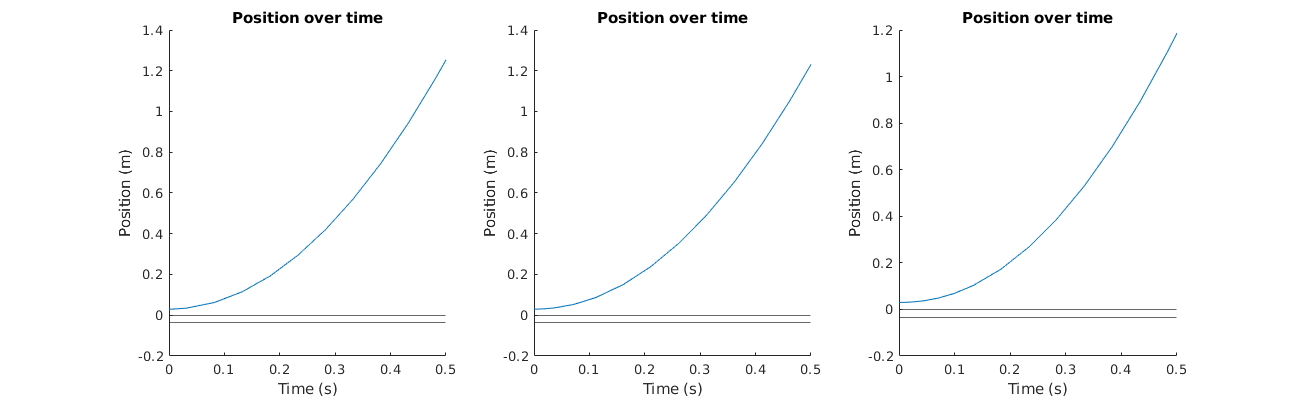

y0 = [0.03; 0];
tspan = [0 0.5];

v_vals = [0.1, 1.5, 4];

figure()
set(gcf, 'position', [0, 0, 1300, 400])
for i = 1 : length(v_vals)
    
    [t, y] = sim_magnet(tspan, y0, v_vals(i), struct_params);

    no_vals = length(v_vals);
    subplot(1, no_vals, i)
    hold on
    plot(t, y(:, 1))
    yline(0)
    yline(-struct_params.l)
    title("Position over time")
    xlabel("Time (s)")
    ylabel("Position (m)")
end

Increasing the voltage creates a strengthened magnetic field, which causes the magnet to move as expected.

## Increasing k's

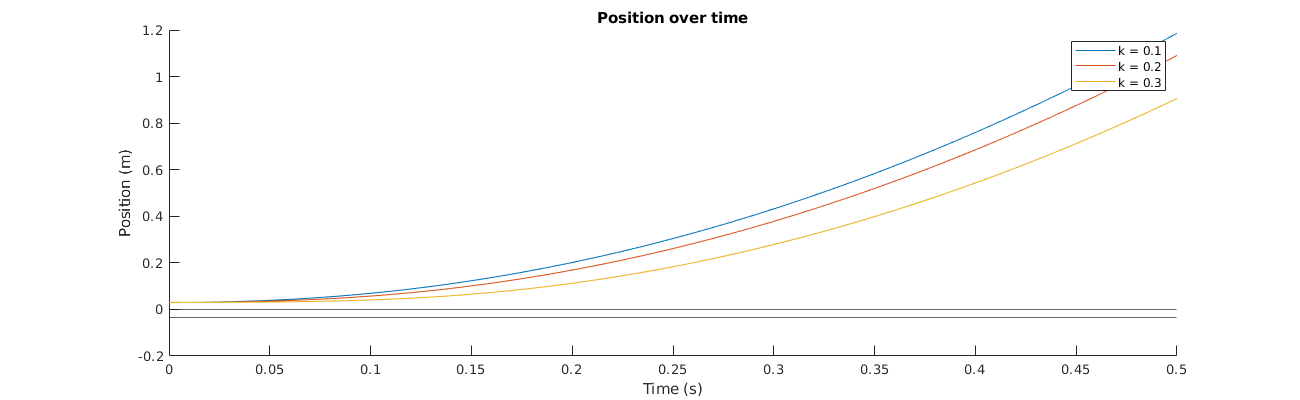

y0 = [0.03; 0];
tspan = linspace(0, 0.5, 100);

k_vals = [0.1, 0.2, 0.3];
v = 2;

figure()
hold on

mat_z = zeros(length(tspan), 3);

set(gcf, 'position', [0, 0, 1300, 400])
for i = 1 : length(k_vals)
    struct_params_i = struct_params;
    struct_params_i.k = k_vals(i);
    [t, y] = sim_magnet(tspan, y0, v, struct_params_i);
    mat_z(:, i) = y(:, 1);
    
    no_vals = length(v_vals);
    plot(t, y(:, 1))
end
yline(0)
yline(-struct_params.l)
title("Position over time")
xlabel("Time (s)")
ylabel("Position (m)")
legend("k = " + string(num2cell(k_vals)))

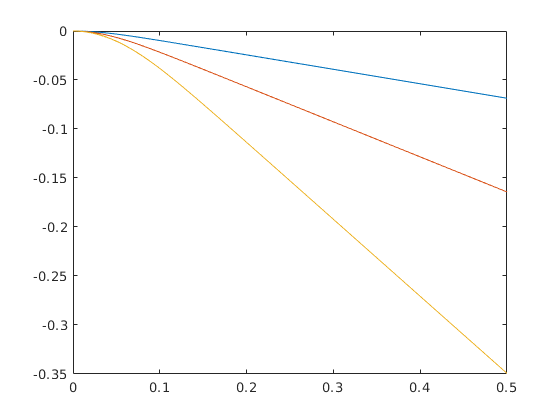

z_grav = 0.5*9.8*t.^2;
mat_z_rectified = mat_z - repelem(z_grav, 1, 3) - y0(1);
figure()
plot(t, mat_z_rectified)

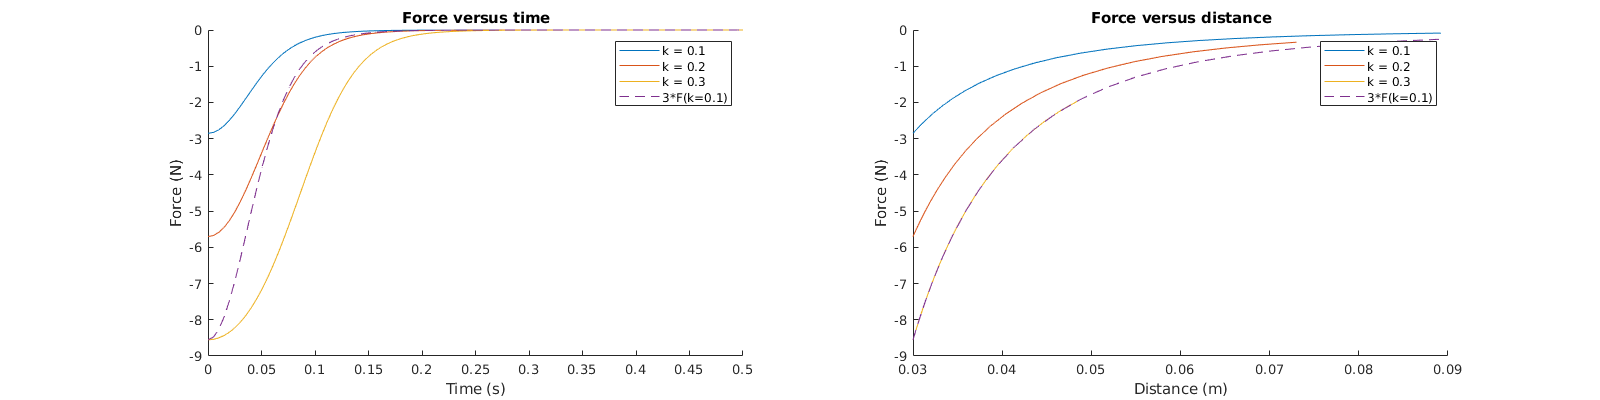

mat_force = zeros(size(mat_z));
for i = 1 : length(k_vals)
    struct_params_i = struct_params;
    struct_params_i.k = k_vals(i);
    mat_force(:, i) = F_iz(v/struct_params.R, mat_z(:, i), struct_params_i);
end
figure()
set(gcf, 'position', [0, 0, 1600, 400])

subplot(1, 2, 1)
hold on
plot(t, mat_force)
plot(t, mat_force(:, 1)*3, '--')
title("Force versus time")
xlabel("Time (s)")
ylabel("Force (N)")
legend(["k = " + string(num2cell(k_vals)), "3*F(k=0.1)"])

subplot(1, 2, 2)
hold on
plot(mat_z(1:end/4, :), mat_force(1:end/4, :));
plot(mat_z(1:end/4, 1), mat_force(1:end/4, 1)*3, '--')
title("Force versus distance")
xlabel("Distance (m)")
ylabel("Force (N)")
legend(["k = " + string(num2cell(k_vals)), "3*F(k=0.1)"])

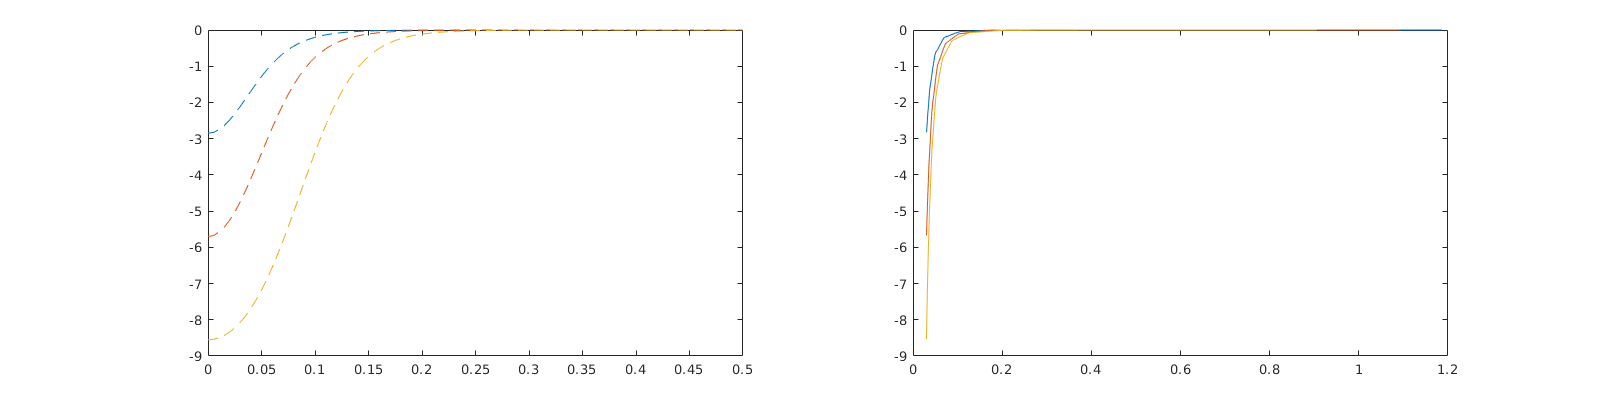

dt = mean(diff(t));
f_t_numeric = diff(diff(mat_z))/dt^2 - 9.8;

figure()
set(gcf, 'position', [0, 0, 1600, 400])

hold on
subplot(1, 2, 1)
plot(t(3:end), f_t_numeric)
plot(t, mat_force, '--')

subplot(1, 2, 2)
plot(mat_z(3:end, :), f_t_numeric)

## Varying Starting Positions

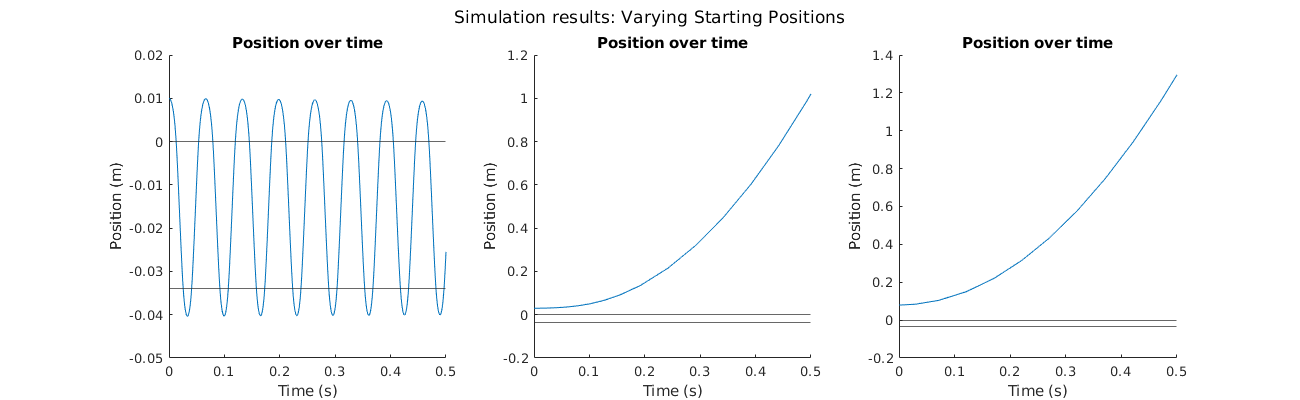

tspan = [0 0.5];

v = 10;

figure()
sgtitle("Simulation results: Varying Starting Positions")
set(gcf, 'position', [0, 0, 1300, 400])

% Sweep through different starting positions
y0_vals = [0.01, 0.03, 0.08];
for i = 1 : length(y0_vals)
    y0 = [y0_vals(i); 0];
    
    [t, y] = sim_magnet(tspan, y0, v, struct_params);

    subplot(1, length(y0_vals), i)
    hold on;
    plot(t, y(:, 1))
    yline(0)
    yline(-struct_params.l)
    title("Position over time")
    xlabel("Time (s)")
    ylabel("Position (m)")
end

As we can see, varying the starting position causes the response to change as expected.

## Simulation Code

function [t, y] = sim_magnet(tspan, y0, v_in, struct_params)
    g = 9.8; %m/s^2
        
    f_rates = @(t, y) ( ...
        rates_current(y, v_in)...
    );
    
    [t, y] = ode23(f_rates, tspan, y0);
    
    function rates = rates_current(y, v_in) % provide u as a function of y
        % Velocity
        rates(1,1) = y(2);
        
        % Acceleration
        rates(2,1) = F_iz(v_in/struct_params.R, y(1), struct_params) + g;
    end
end
